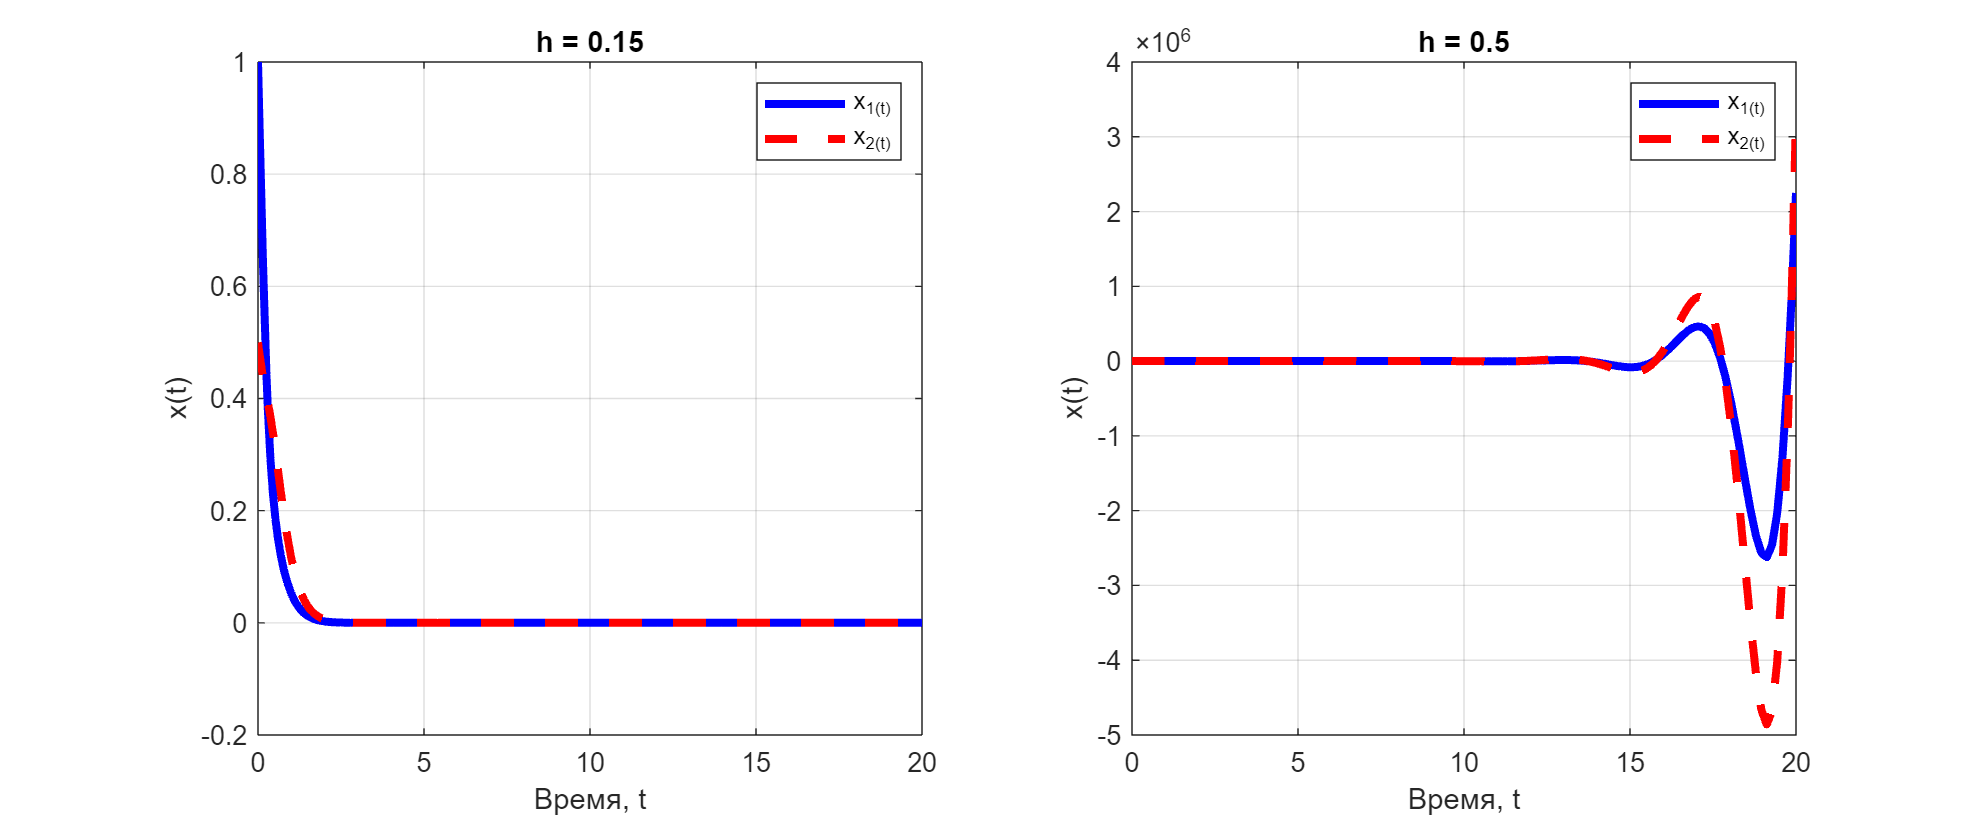

A = [-1, 2; -1, 3];
A1 = [-2, -1; 1, -4];
x0 = [1; 0.5];
tspan = [0, 20];

h1 = 0.15;
sol1 = dde23(@(t, y, Z) A*y + A1*Z, h1, @(t) x0, tspan);

h2 = 0.5;
sol2 = dde23(@(t, y, Z) A*y + A1*Z, h2, @(t) x0, tspan);

figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(sol1.x, sol1.y(1, :), 'b-', 'LineWidth', 3); hold on;
plot(sol1.x, sol1.y(2, :), 'r--', 'LineWidth', 3);
grid on; xlabel('Время, t'); ylabel('x(t)');
title(['h = ', num2str(h1)]);
legend('x_1(t)', 'x_2(t)');

subplot(1, 2, 2);
plot(sol2.x, sol2.y(1, :), 'b-', 'LineWidth', 3); hold on;
plot(sol2.x, sol2.y(2, :), 'r--', 'LineWidth', 3);
grid on; xlabel('Время, t'); ylabel('x(t)');
title(['h = ', num2str(h2)]);
legend('x_1(t)', 'x_2(t)');

saveas(gcf, '1.png');

test_h = 0.31:0.001:0.33;
tspan = [0 1000];

for i = 1:length(test_h)
    h = test_h(i);
    sol = dde23(@(t, y, Z) A*y + A1*Z, h, @(t) x0, tspan);

    if sol.x(end) < tspan(2) * 0.9
        fprintf('h=%.3f: Неустойчиво (обрыв решения при t=%.1f)\n', h, sol.x(end));
    else
        last_10_percent = round(length(sol.x)*0.9):length(sol.x);
        x_last = sol.y(:, last_10_percent);
        avg_norm = mean(sqrt(sum(x_last.^2, 1)));
        
        if avg_norm < 0.01
            fprintf('h=%.3f: устойчиво (ср.норма=%.2f)\n', h, avg_norm);
        else
            fprintf('h=%.3f: неустойчиво (ср.норма=%.2f)\n', h, avg_norm);
            break;
        end
    end
end

h=0.310: устойчиво (ср.норма=0.00)
h=0.311: устойчиво (ср.норма=0.00)
h=0.312: устойчиво (ср.норма=0.00)
h=0.313: устойчиво (ср.норма=0.00)
h=0.314: устойчиво (ср.норма=0.00)
h=0.315: устойчиво (ср.норма=0.00)
h=0.316: устойчиво (ср.норма=0.00)
h=0.317: устойчиво (ср.норма=0.00)
h=0.318: устойчиво (ср.норма=0.00)
h=0.319: устойчиво (ср.норма=0.00)
h=0.320: устойчиво (ср.норма=0.00)
h=0.321: устойчиво (ср.норма=0.00)


h=0.322: неустойчиво (ср.норма=0.22)


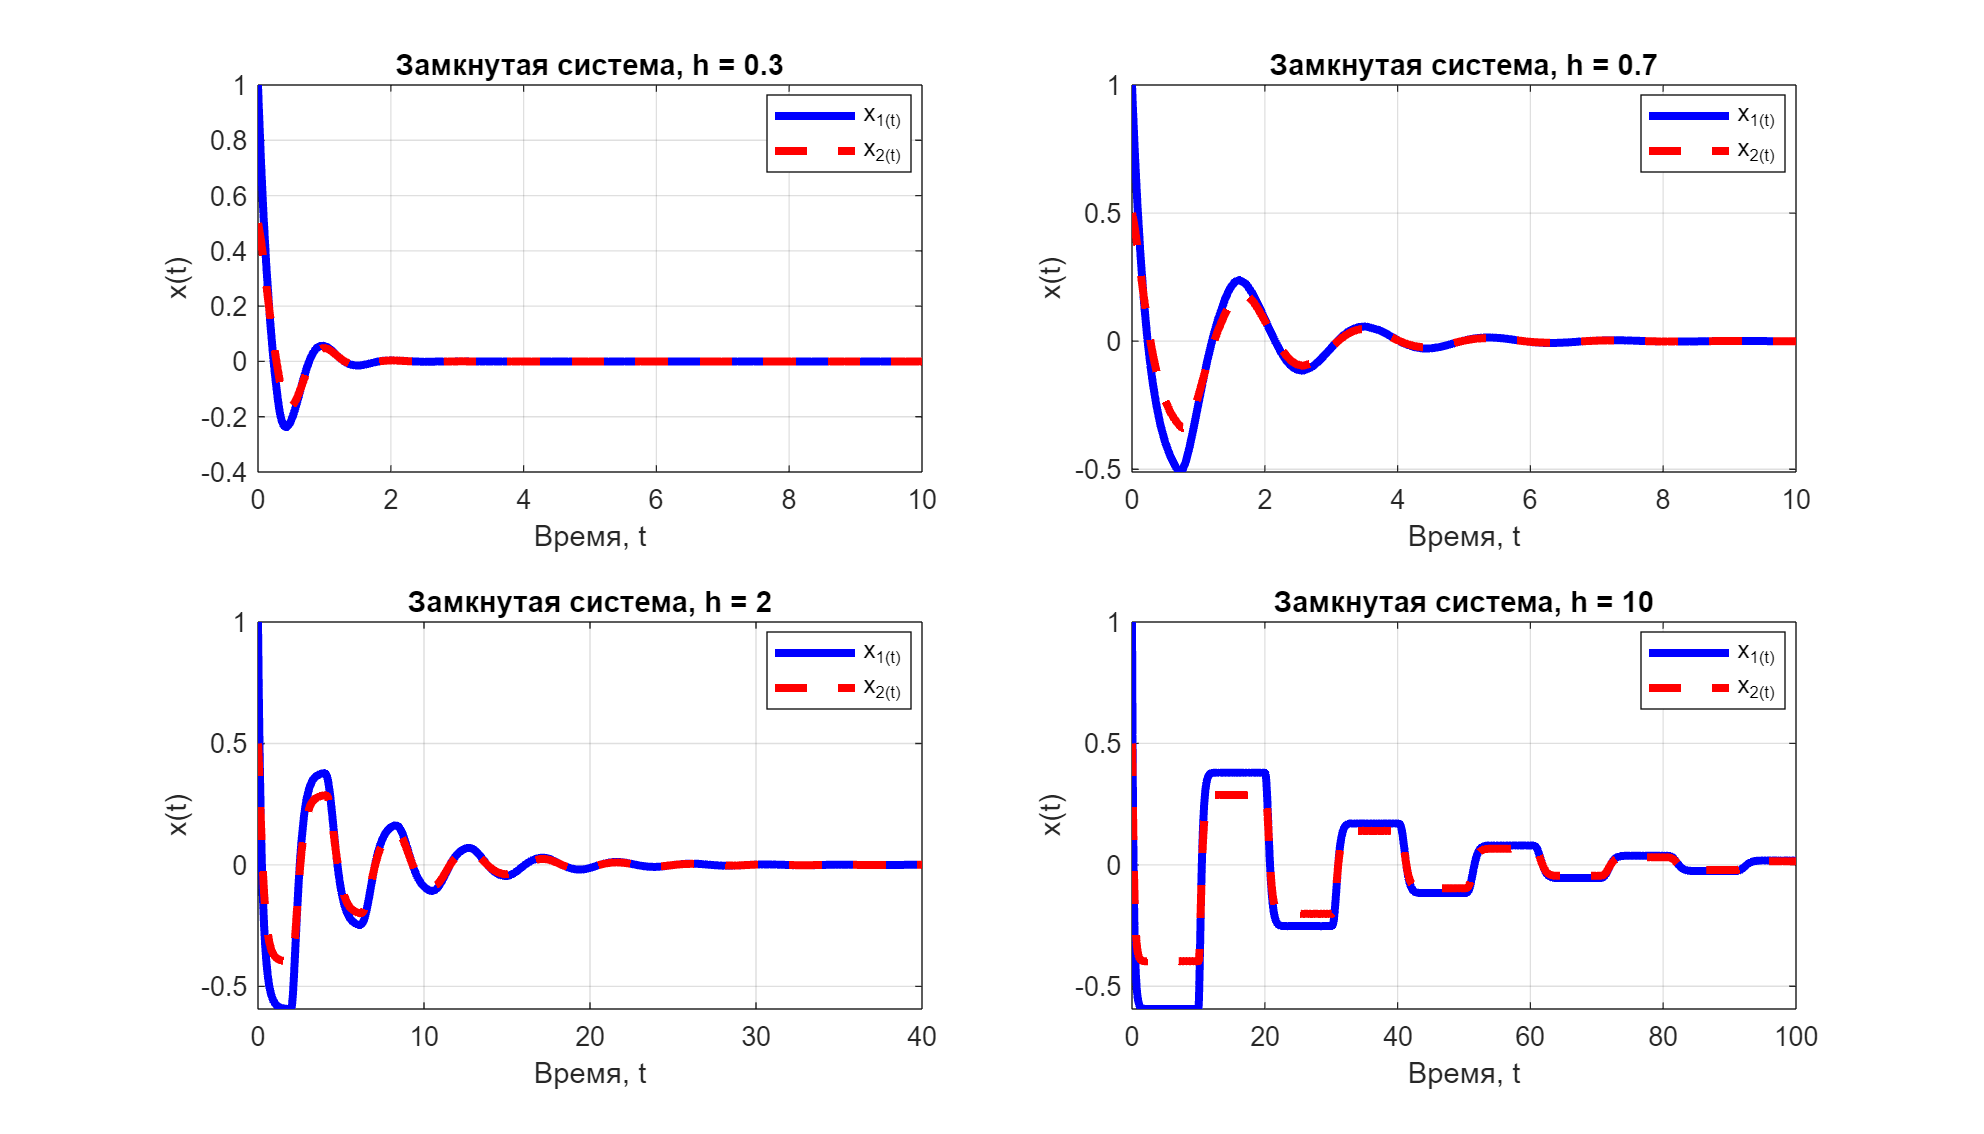

K_use = [-3.543783  -1.507099;
      6.302449 -13.448608];

delays = [0.30 0.7 2 10];
tspan_vis = [0 100];
xlims = [ 10 10 40 100];
figure('Position', [150, 150, 1400, 800]);

for i = 1:length(delays)
    h = delays(i);
    
    sol = dde23(@(t,y,Z) (A + K_use)*y + A1*Z, ...
                h, @(t) x0, tspan_vis);
    
    subplot(2,2,i);
    plot(sol.x, sol.y(1,:), 'b-', 'LineWidth', 3); hold on;
    plot(sol.x, sol.y(2,:), 'r--', 'LineWidth', 3);
    
    grid on;
    xlabel('Время, t');
    ylabel('x(t)');
    xlim([0 xlims(i)]);
    title(['Замкнутая система, h = ', num2str(h)]);
    legend('x_1(t)', 'x_2(t)', 'Location','best');
end

saveas(gcf, 'closed_delays.png');